We consider the IVP $u'=\sin[(u+t)^2]$ over $0\le t \le 4$, with $u(0)=-1$. 

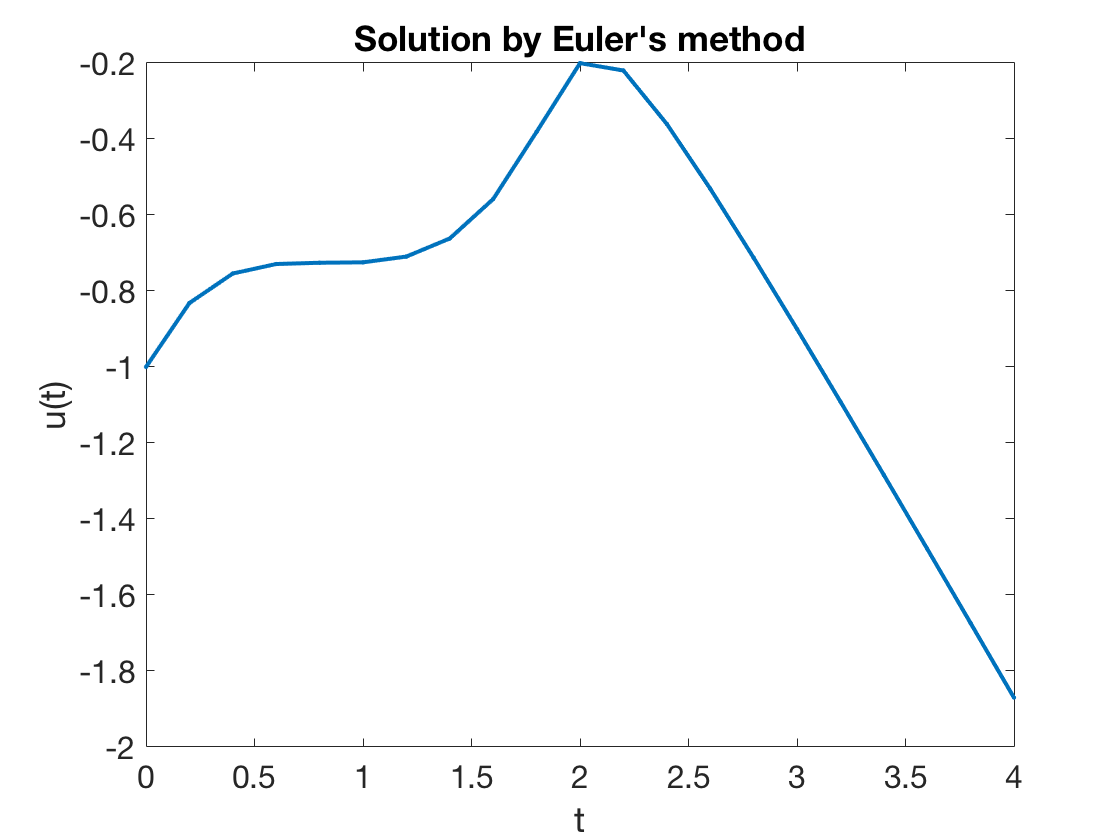

f = @(t,u) sin( (t+u).^2 );
a = 0;  b = 4;
u0 = -1;
[t,u] = eulerivp(f,[a,b],u0,20);
plot(t,u,'.-')
xlabel('t'), ylabel('u(t)'), title('Solution by Euler''s method')  % ignore this line

We could define a different interpolant to get a smoother picture above, but the derivation assumed the piecewise linear interpolant, so it is the most meaningful one. We can instead request more steps to make the interpolant look smoother.

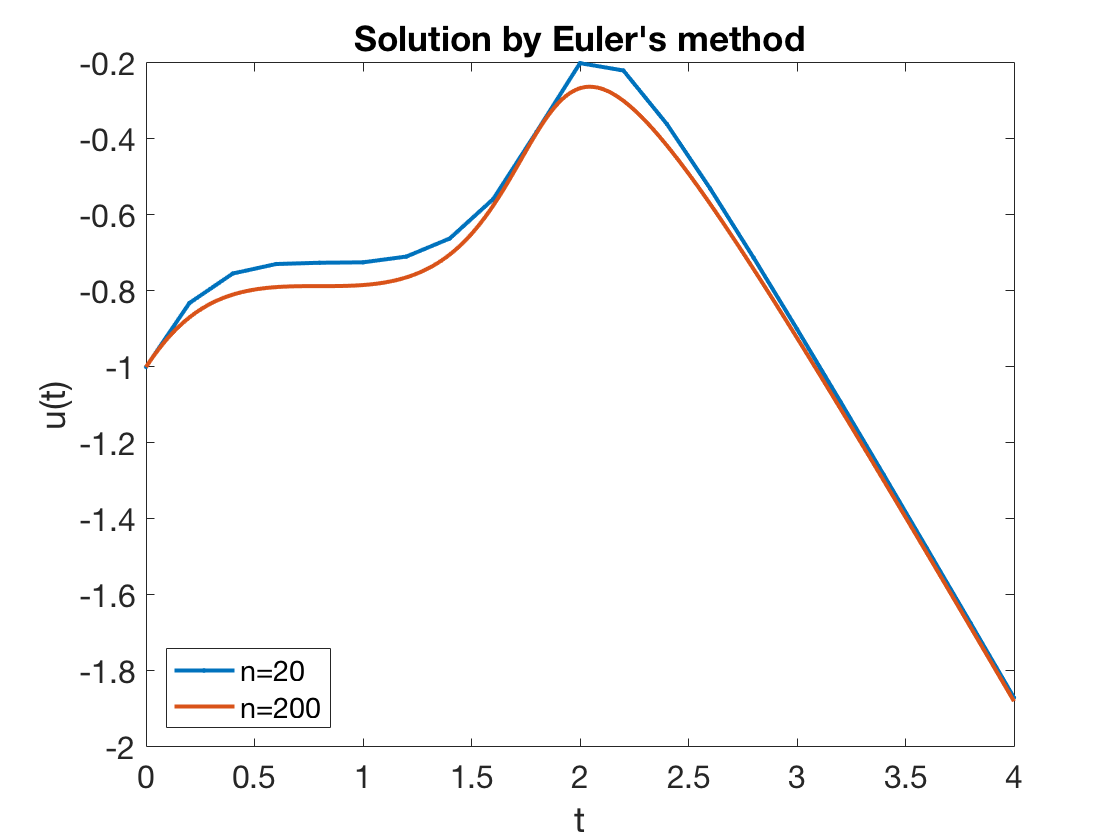

[t,u] = eulerivp(f,[a,b],u0,200);
hold on, plot(t,u,'-')
legend('n=20','n=200','location','southwest')  % ignore this line

Increasing $n$ changed the solution noticeably. Since we know that interpolants and finite differences become more accurate as $h\to 0$, we should expect that from Euler's method too.

We don't have an exact solution to compare to, so we will use the built-in solver `ode113` with settings chosen to construct an accurate solution. 

opt = odeset('abstol',5e-14,'reltol',5e-14);  
uhat = ode113(f,[a,b],u0,opt);
u_exact = @(t) deval(uhat,t)';
fplot(u_exact,[a,b],'k-')

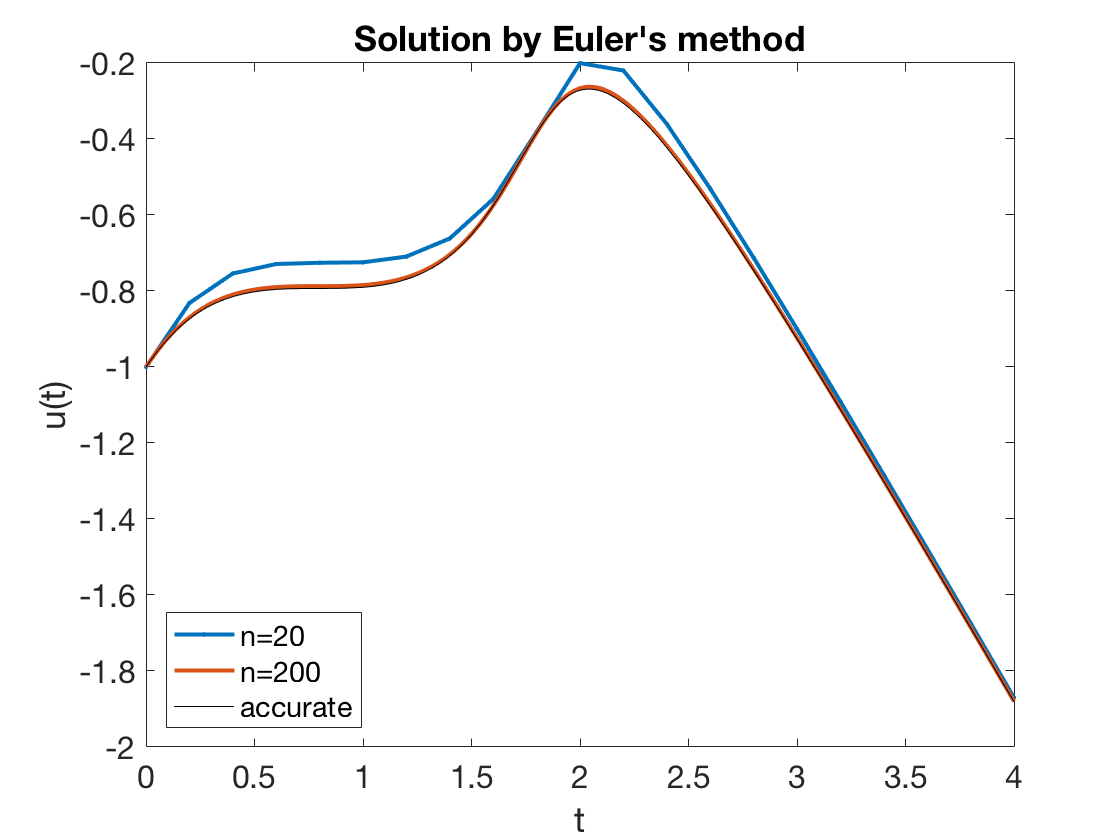

legend('n=20','n=200','accurate','location','southwest')  % ignore this line

Now we can perform a convergence study. 

n = 50*2.^(0:5)';
err = 0*n;
for j = 1:length(n)
    [t,u] = eulerivp(f,[a,b],u0,n(j));
    err(j) = max(abs(u_exact(t)-u));
end
table(n,err)

ans = 6×2 table
        n            err    
    __________    __________

    5.0000e+01    2.9996e-02
    1.0000e+02    1.4229e-02
    2.0000e+02    6.9443e-03
    4.0000e+02    3.4295e-03
    8.0000e+02    1.7041e-03
    1.6000e+03    8.4942e-04


The error is almost perfectly halved at each step, so we expect that a log-log plot will reveal first-order convergence.

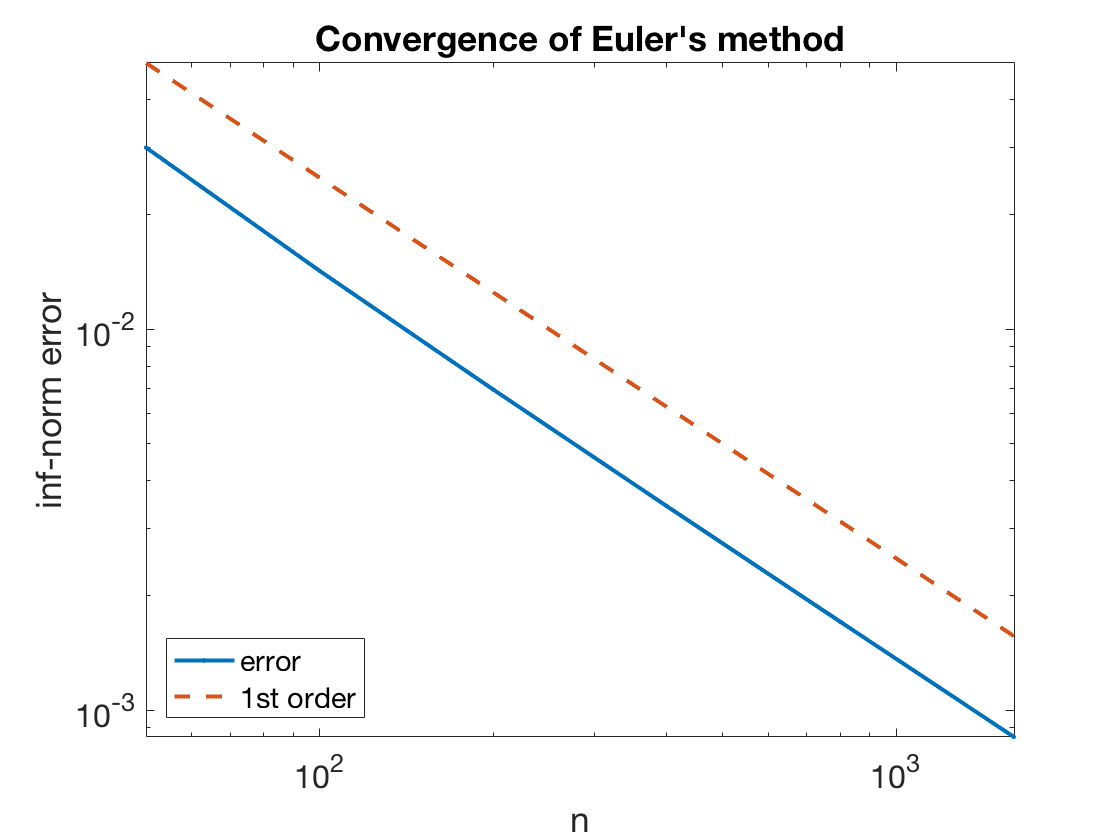

clf
loglog(n,err,'.-'), hold on
loglog(n,0.05*(n/n(1)).^(-1),'--')
axis tight, xlabel('n'), ylabel('inf-norm error')  % ignore this line
title('Convergence of Euler''s method')  % ignore this line
legend('error','1st order','location','southwest')  % ignore this line